# Off-Board Charger for Electric Vehicles

## **Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

Some interactions require basic MATLAB familiarity. If you need a refresher, MATLAB Onramp is a free, two-hour tutorial that covers the essentials.[](https://www.mathworks.com/learn/tutorials/matlab-onramp.html)

Work through the sections in order. Some sections use variables created earlier, so running sections out of sequence may produce errors.

## 1. Introduction

An **off-board charger** is a type of battery charging system designed to recharge electric vehicles (EVs) or other battery-powered systems. Unlike on-board chargers, which are integrated into the vehicle, off-board chargers are standalone devices. These chargers are commonly found at charging stations or in facilities where high-powered and rapid charging is needed.

Off-board chargers are particularly suited for scenarios requiring high charging power or where space constraints in the vehicle make it impractical to include a high-capacity charging system. They can deliver direct current (DC) power directly to the battery, bypassing the vehicle’s onboard charger. This approach enables faster charging and greater efficiency compared to alternating current (AC) charging, which requires conversion within the vehicle.

By the end of this activity, you should be able to explain how an off-board charger manages high-power AC-DC and DC-DC conversion, charging-stage control, and grid synchronization.

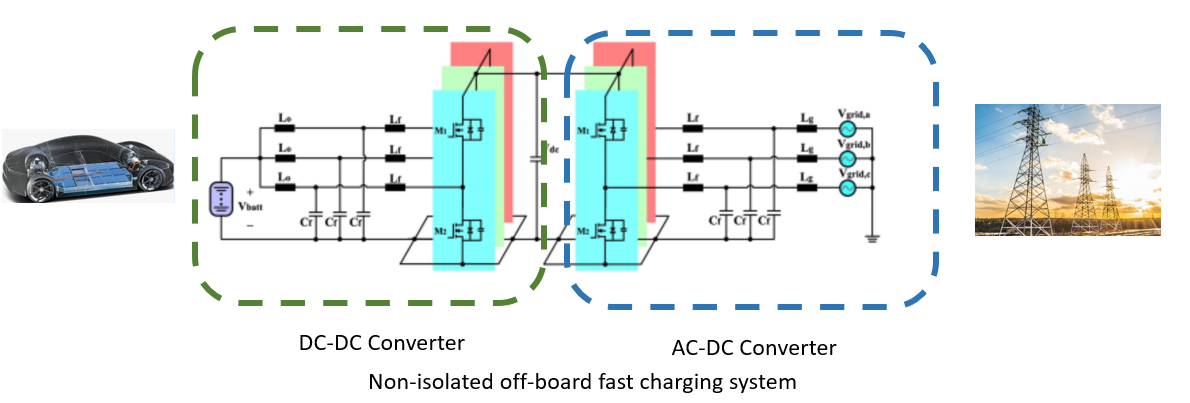

## 2. Charging the battery

Battery charging must balance speed, safety, and battery life. Most charging profiles use two stages: constant-current charging and constant-voltage charging.

- **Constant Current (CC) Stage**:

- During the initial phase, the off-board charger supplies a constant current (e.g., 20 A as shown in the graph) to the battery while the voltage gradually increases.

- This stage is used to rapidly charge the battery up to around 70-80% of its capacity.

- The main goal here is to quickly reach a target voltage while ensuring safe thermal conditions.

         2. **Constant Voltage (CV) Stage**:

- Once the battery reaches its target voltage (e.g., 115 V), the charging mode switches to **Constant Voltage**. Here, the voltage is held steady, while the current gradually decreases as the battery approaches full charge.

- This stage is crucial for topping off the remaining charge to reach 100% charge without overcharging, which could degrade the battery over time.

- The gradual reduction of current protects the battery cells, extending their lifespan by preventing over-voltage and thermal stress.

This dual-phase approach optimizes charging speed, efficiency, and battery health.

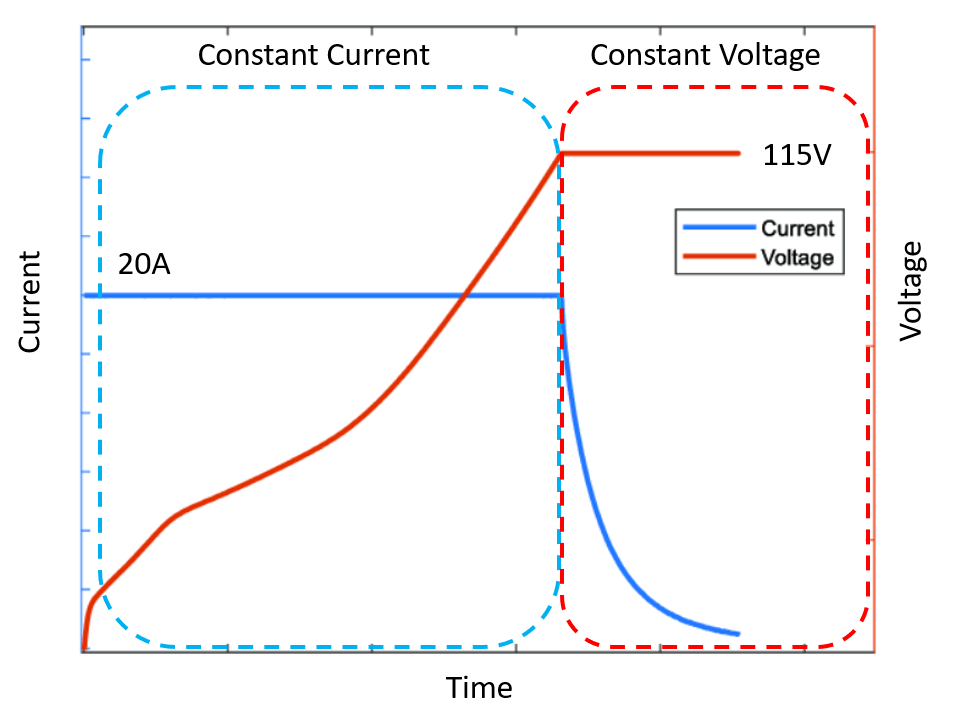

State of charge (SOC) measures the battery charge as a percentage of full charge. In this model, SOC helps you identify where the charging process transitions between stages. SOC is calculated as follows:


$$\[ SOC = 100 \left( 1 - \frac{1}{Q} \int_0^t i(t) \, dt \right) \]$$


This model represents a fast charger that uses a high-voltage AC source (480 V line-to-line) to charge the battery. Because the charging current and power are much higher than in an on-board charger, the control system must regulate current and voltage carefully.

## 3. Circuit

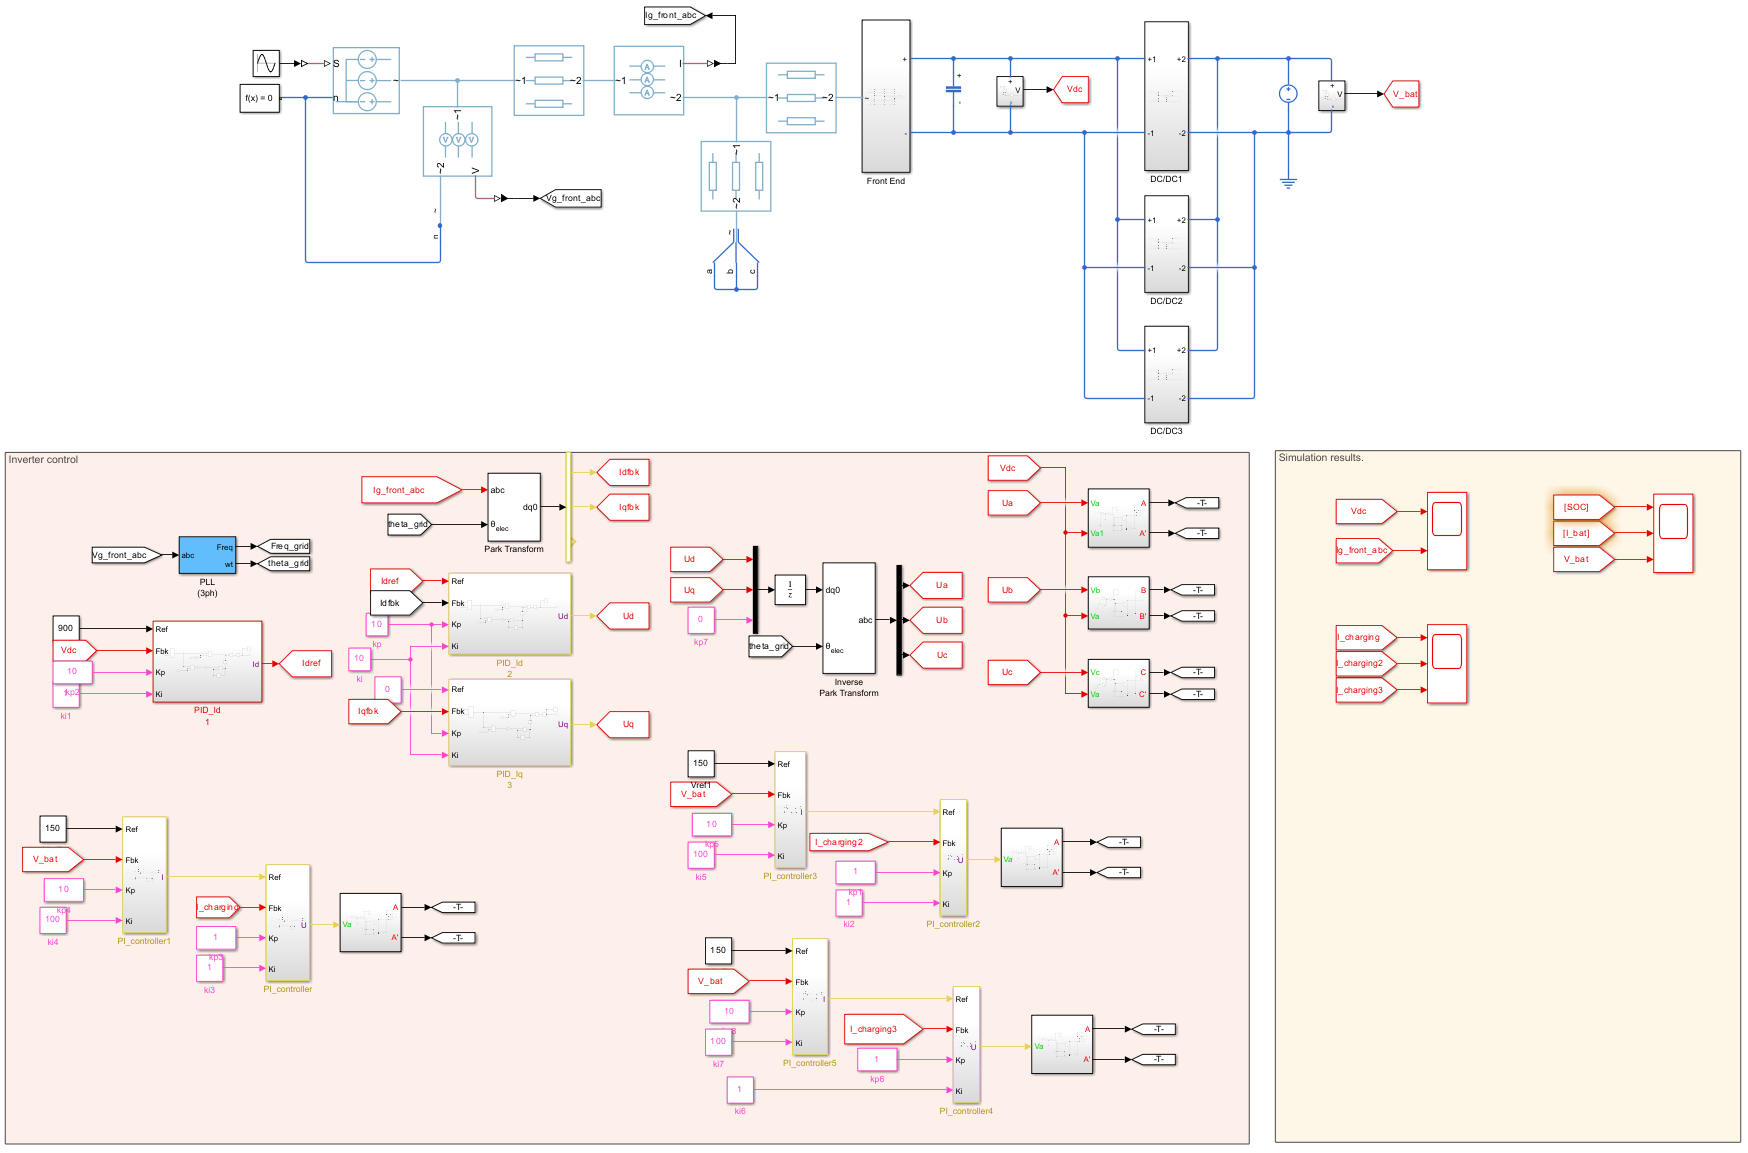

Click the button below to open the model.

 
open_system('Models/offboard_SSC_simscape.slx')
if ~exist('V_ref','var')
    V_ref = 900;  
end

Select from the menu below to learn more about different parts of the model.

switchRectifier("No Selection");

### 3.1 Isolated Off-Board Charger

This section provides an isolated off-board charger model for comparison. Open the isolated model and identify how isolation changes the converter structure.[](matlab:open('Isooffboard_SSC.slx'))

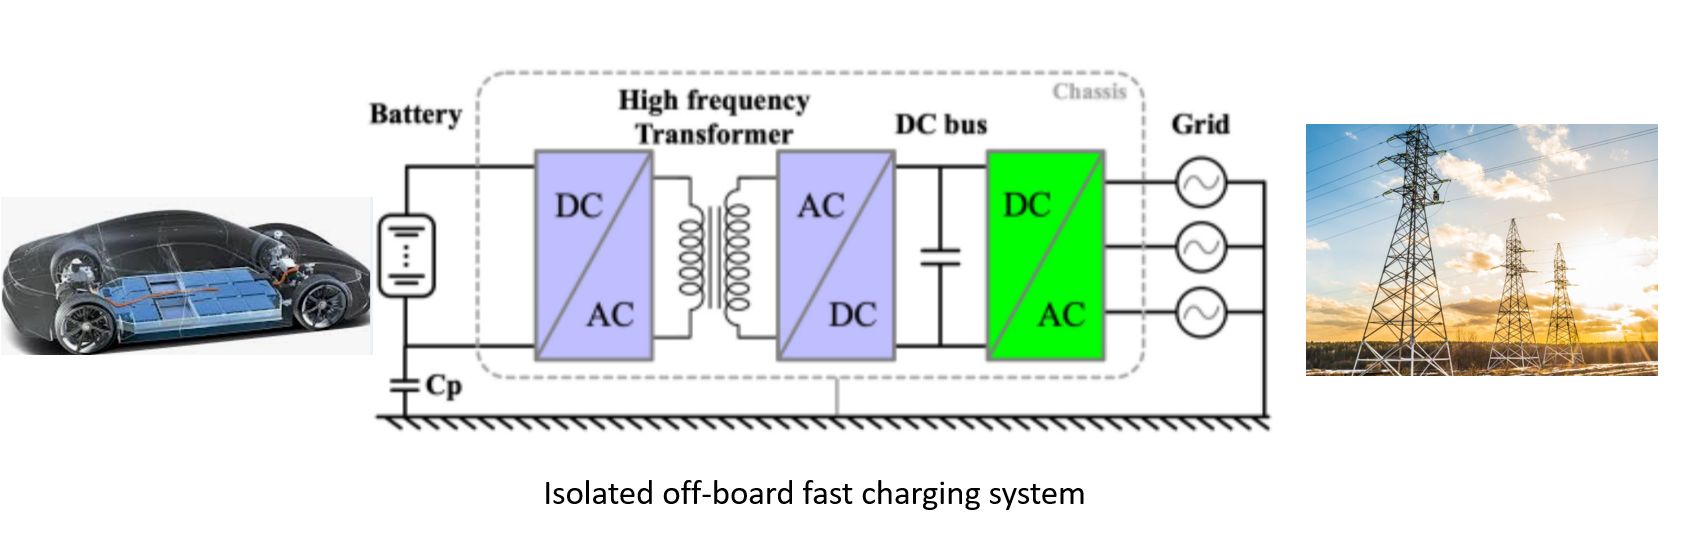

### 3.2 Connect to the Grid

For this simulation, the inverter output must match the grid frequency and phase angle. A phase-locked loop (PLL) estimates the grid phase and frequency. You do not need to analyze the PLL internals here; focus on how synchronization supports grid connection.

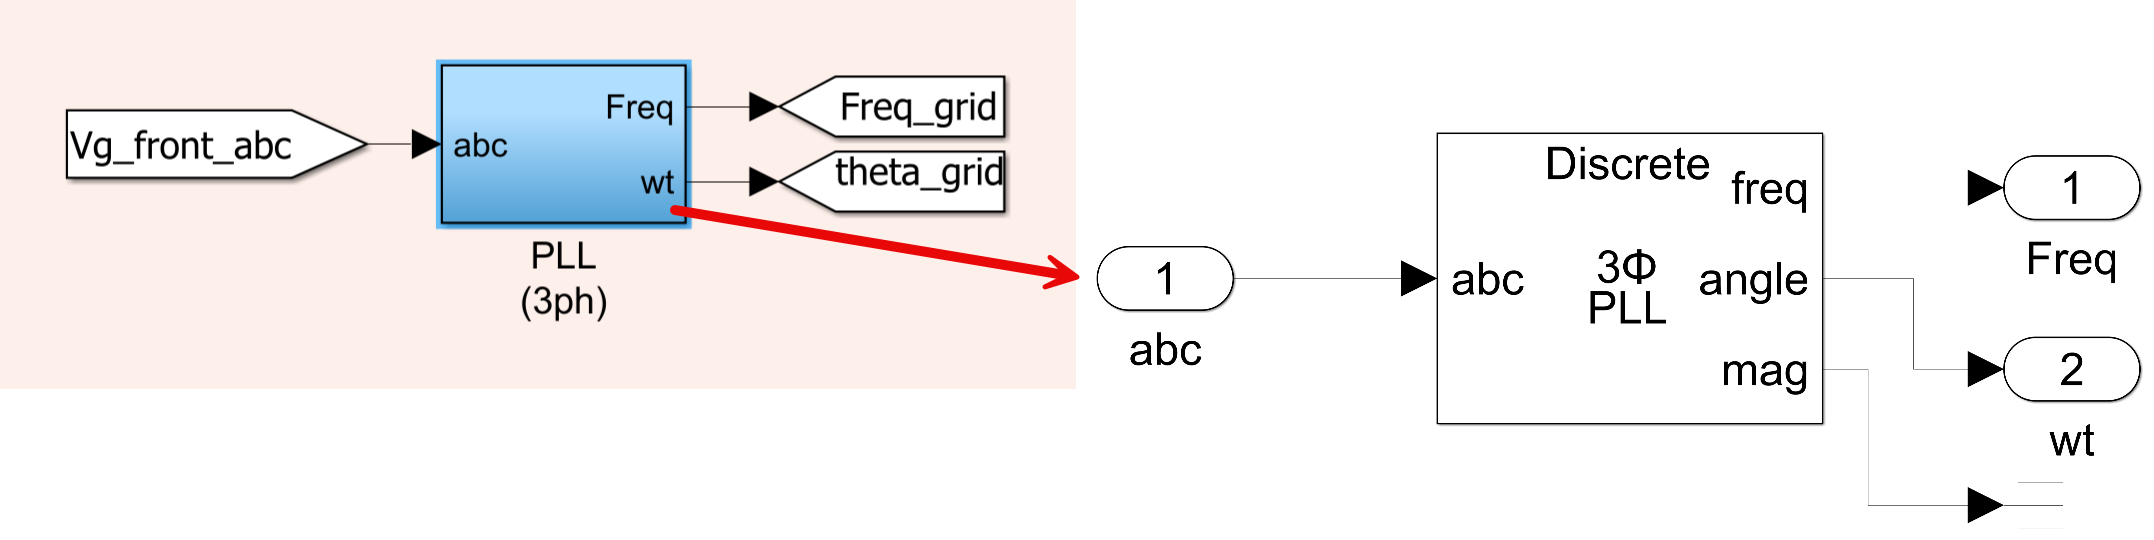

## 4. Control Algorithm

The control algorithm has three parts:

- Charging current/voltage control

- Inverter and DC bus control

- Second-Order Generalized Integrator (SOGI)

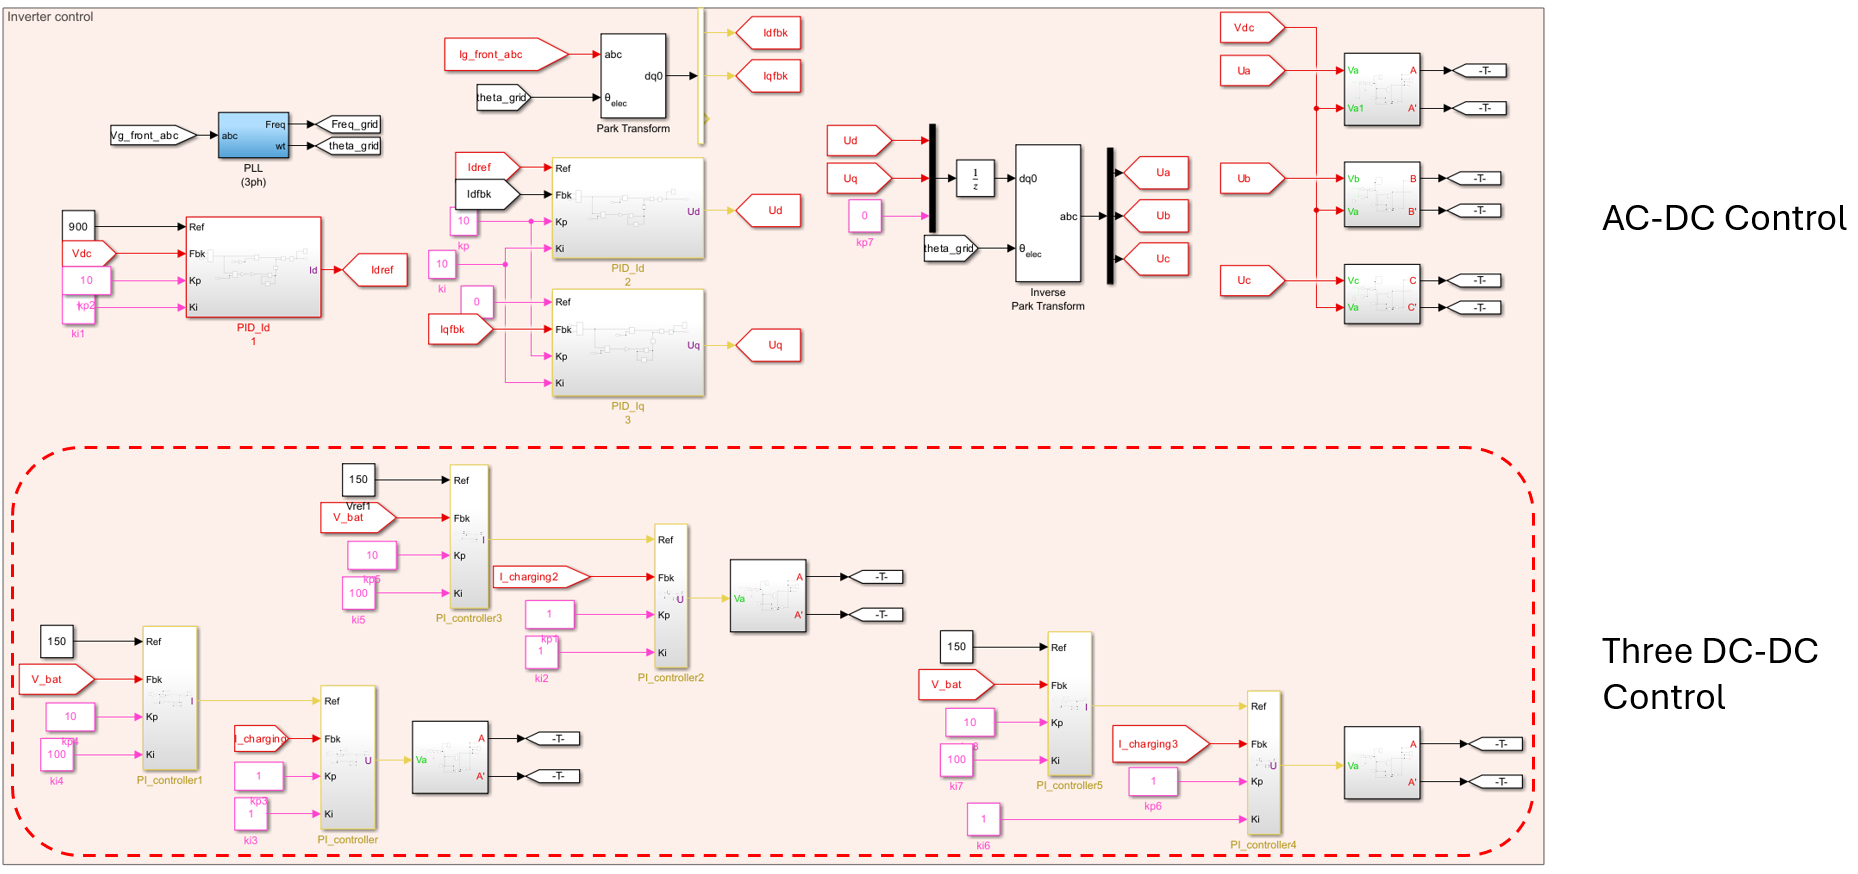

### 4.1 Charging current and voltage control

The control algorithm is designed around two charging stages: constant-current charging and constant-voltage charging.

For each DC-DC converter, two PI controllers are used to control the charging voltage and charging current. In this model, the charging voltage is set to 150 V and the charging current to 50 A for each converter.

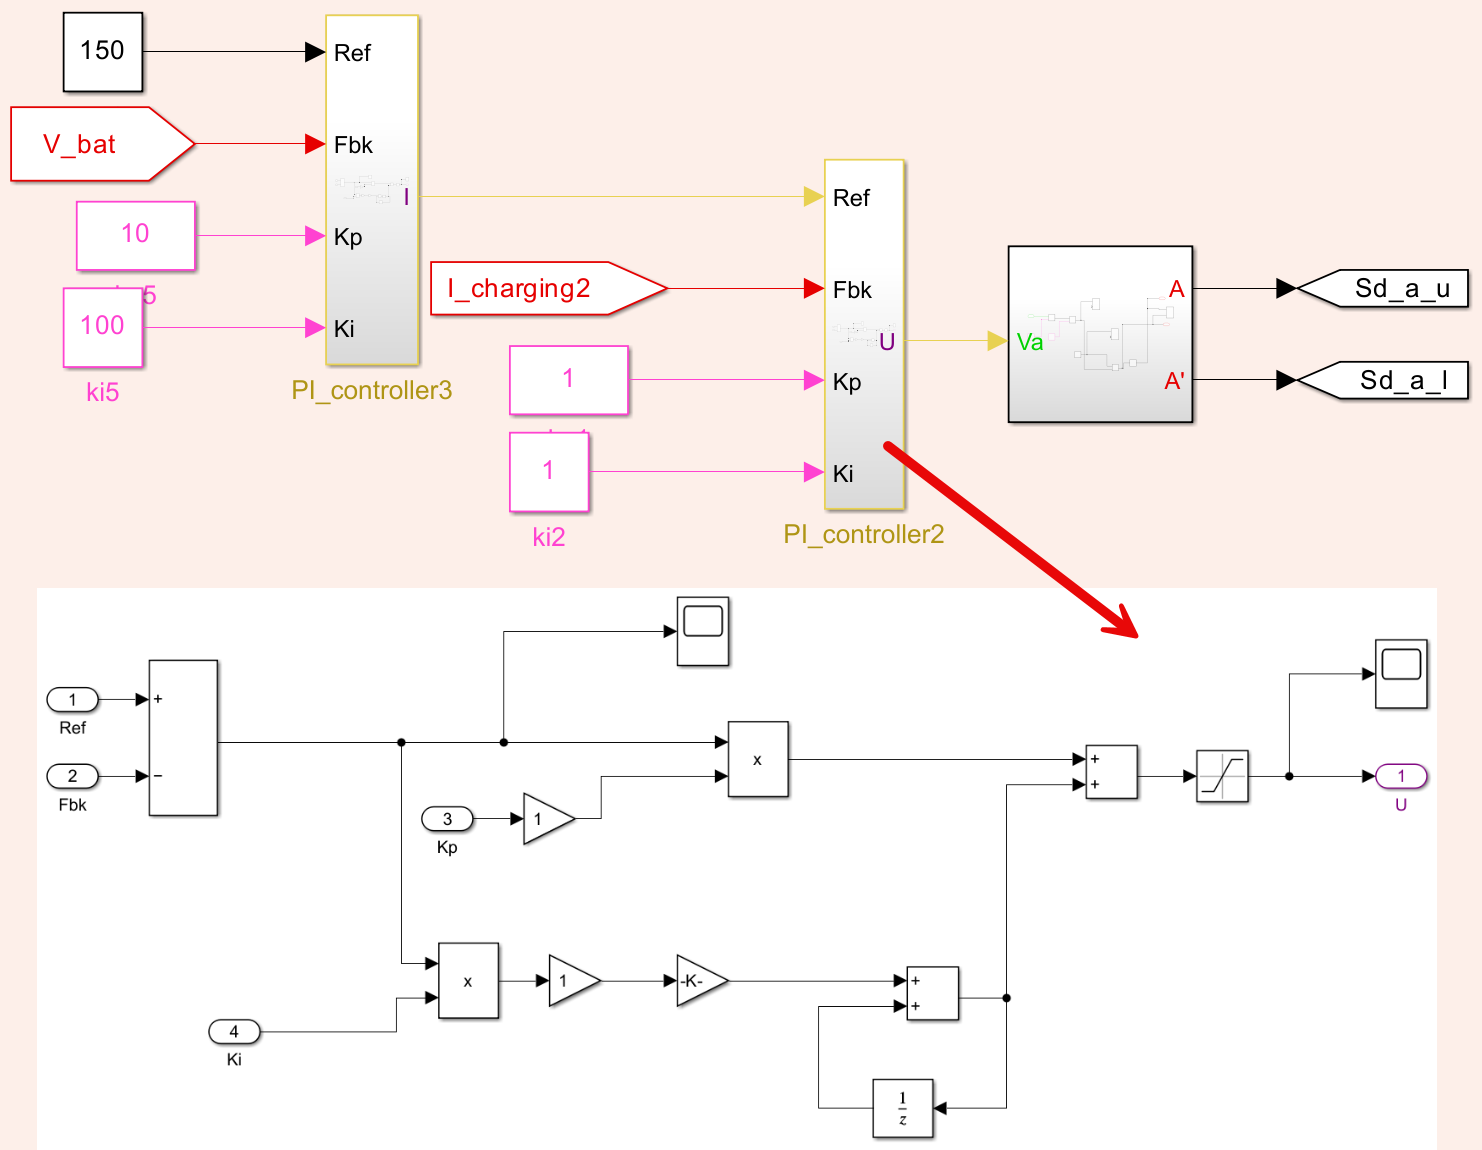

**Constant-current charging stage configuration.**

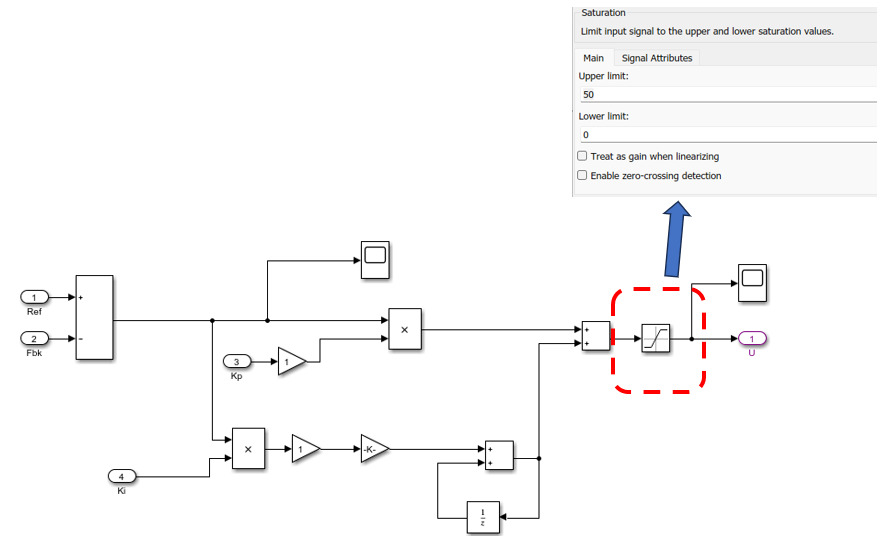

### 4.2 Inverter and DC Bus Control

The inverter control combines current control, voltage control, and duty-cycle generation.

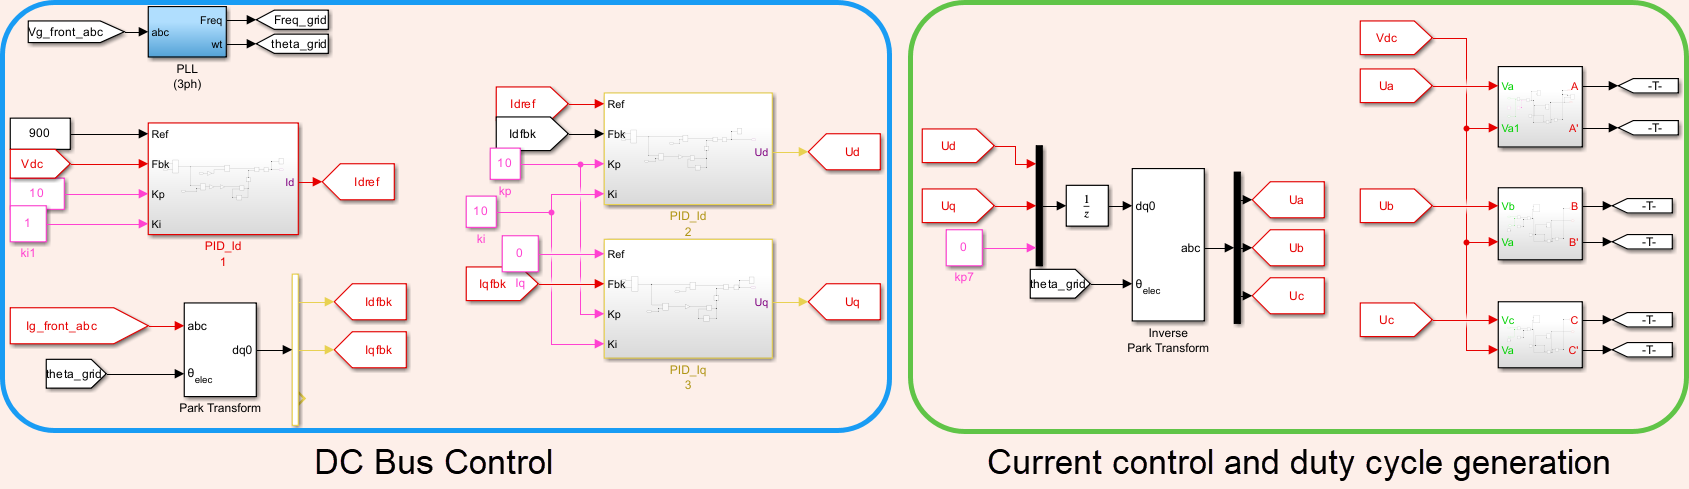

Use the menu below to inspect each part of the controller and connect it to the plotted responses.

controller("No Selection")

Vdc is the DC output voltage. Changing its reference value strongly affects the output voltage and output power. The default value is 900 V.

Before changing V_ref, predict how a higher DC-bus voltage reference will affect output voltage and output power. Then adjust the slider and compare the results with your prediction.

V_ref=860;
disp("Please wait for the simulation to finish. This may take a few minutes")
 
run_offboard(V_ref)
disp("Simulation completed. You can now analyze the results")

## 5. Analyzing the results

Run the model if you have not done so already. After the simulation is complete (this may take a few minutes), use the scopes to evaluate the charging behavior.

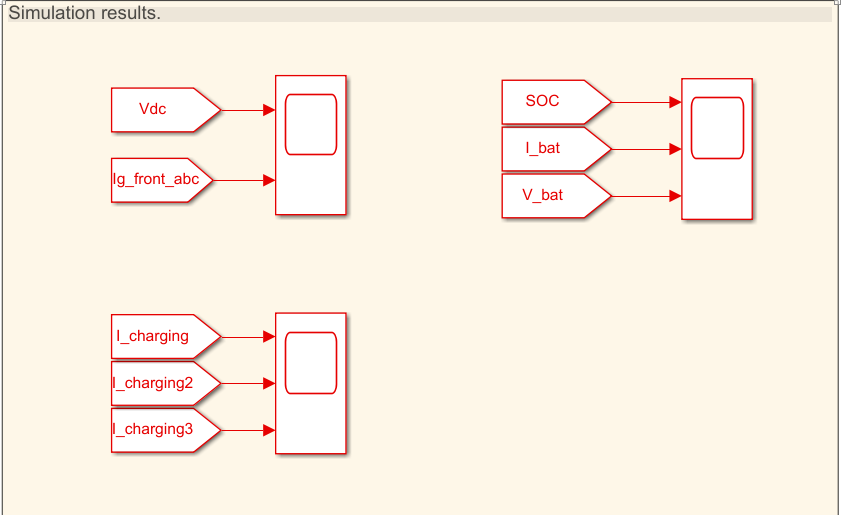

Before changing the initial SOC, predict whether the model will spend more time in constant-current charging or constant-voltage charging. Then change the initial SOC and identify where the charging mode changes.

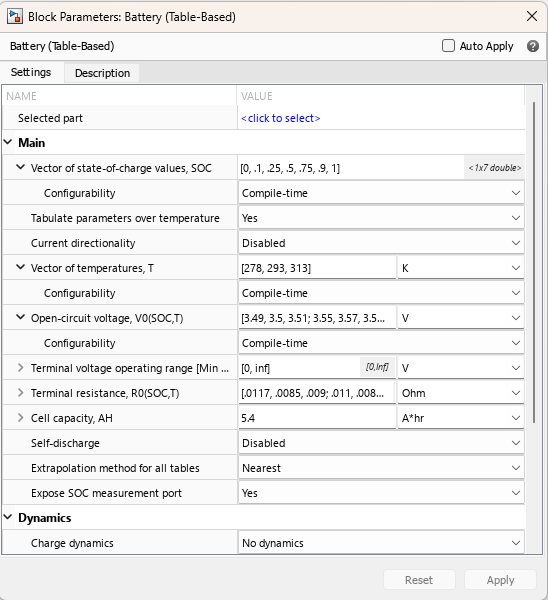

Use the menu below to compare your results with the reference simulation results.

result("No Selection")

## 6. Exercise

Exercise 1. What is the conversion sequence from the power grid to the battery in off-board charging? Reflect on why each conversion stage is needed.

exerciseSol1(...
     false, ...
   false);
 

Exercise 2. Why are there three DC-DC converters in this model? Now think of how that structure affects charging power.

exerciseSol2(...
     false, ...
   false,...
  false);
 

Exercise 3. Use the simulation results to explain what may happen if the charging current is set too high.

exerciseSol3(...
     false, ...
   false,...
   false);
 

## 7. Conclusion

This activity connected high-power conversion, battery charging stages, and control-system behavior in an off-board charger. After completing it, you should be able to use simulation plots to explain how charger settings affect current, voltage, power, and SOC.

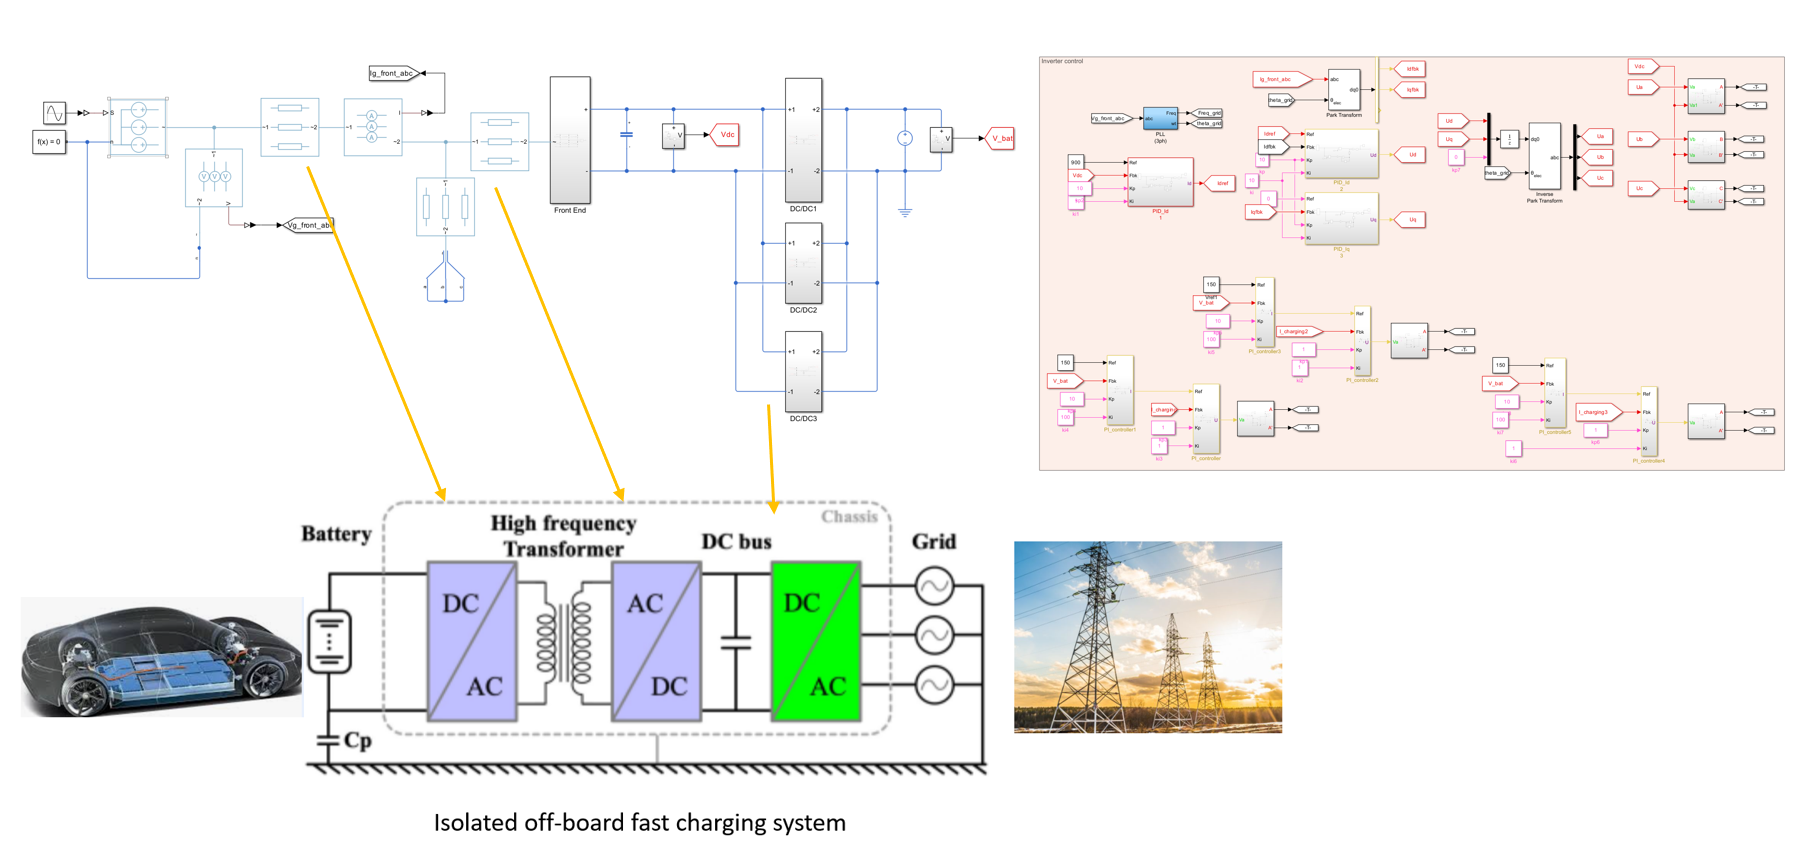

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "Threedc"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/OffBoardCharger/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/OffBoardCharger/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Threedc"
        rect = imread("Images/OffBoardCharger/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
  
    end
end
end


function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/OffBoardCharger/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/OffBoardCharger/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/OffBoardCharger/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Grid" "Battery" "Converter"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Grid"
        rect = imread("Images/OffBoardCharger/Result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Battery"
        rect = imread("Images/OffBoardCharger/Result2.png");
        imshow(rect,"Interpolation","bilinear");
     elseif opt == "Converter"
        rect = imread("Images/OffBoardCharger/Result3.png");
        imshow(rect,"Interpolation","bilinear");
        
    end
end
end


function exerciseSol1(A,B)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        disp("Please select an answer!")
    elseif A && B
        disp("Please select only one answer");
    elseif A
        disp("Correct!")
    else 
        disp("Incorrect. Please review the circuit section again.")
    end
end

function exerciseSol2(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif A+B+C > 1
        disp("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        disp("Incorrect. Please check the control section again")
    end
end
function exerciseSol3(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        disp("Please select an answer!")
    elseif A+B+C > 1
        disp("Please select only one answer")
    elseif C
        disp("Correct!")
    else 
        disp("Incorrect.")
    end
end

function showpic2(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/OffBoardCharger/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end



function run_offboard(V_ref)

    function [t, y] = extract_sig_data(simOut, name)
        if isprop(simOut, name)
            raw = simOut.(name);
        else
            raw = simOut.get(name);
        end
        
        if isa(raw, 'timeseries') 
            t = raw.Time;
            y = squeeze(raw.Data);
        elseif isstruct(raw) && isfield(raw, 'time') 
            t = raw.time;
            y = squeeze(raw.signals.values);
        else
            error(['Signal "' name '" format not supported. Please set To Workspace block to "Structure with Time" or "Timeseries".']);
        end
    end

   assignin('base','V_ref',V_ref);       
    wState = warning('off', 'all');
    try
        simOut = sim('Models/offboard_SSC_simscape.slx'); 
    catch ME
        warning(wState); 
        rethrow(ME);
    end
    warning(wState); 
    out = simOut;

    [time_vdc, vdc_val] = extract_sig_data(out, 'Vdc');
    [~, ibat_val] = extract_sig_data(out, 'I_bat');

    len = min(length(vdc_val), length(ibat_val));
    
    vdc_aligned = vdc_val(1:len);
    ibat_aligned = ibat_val(1:len);
    time_aligned = time_vdc(1:len);
    pdc_val  = vdc_aligned .* ibat_aligned;

    
    fig = figure('Position',[100,100,1000,500]); 
    subplot(1,2,1);
    yyaxis left
    plot(time_aligned, vdc_aligned, 'LineWidth', 1.5); ylabel('V_{dc} (V)');
    yyaxis right
    plot(time_aligned, ibat_aligned,'LineWidth', 1.5); ylabel('I_{bat} (A)');
    xlabel('Time (s)'); title('DC Output Voltage and Battery Current');
    legend('V_{dc}','I_{bat}','Location','best'); grid on;

    subplot(1,2,2);
    plot(time_aligned, pdc_val,'LineWidth',1.5);
    title('DC Output Power'); xlabel('Time (s)'); ylabel('Power (W)'); grid on;
end